arcpoints = load ('hockeyarcpoints.txt','-ascii');
[sizex,~] = size(arcpoints);

arc = 0;
new_label = 0;

cellArc = {};
for i = 1 : sizex
    arc_label = arcpoints(i,1);
    if arc~=arc_label
        if arc > 0
            cellArc{new_label} = H;
        end
        arc = arc_label;
        new_label = new_label+1;
        H = [];
        k = 1;
    end
    H(k,1) = arcpoints(i,2)+1;
    H(k,2) = arcpoints(i,3)+1;
    H(k,3) = arcpoints(i,1);
    k = k + 1;
end
% Successfully saved arcs to cellArc
% coordinate +1, +1

[~, arc_num] = size(cellArc);
thinArc = cell(arc_num,1);
sol = zeros(5,arc_num);
for i = 1 : arc_num
    [point_num,~] = size(cellArc{i});
    img = full(sparse(cellArc{i}(:,1),cellArc{i}(:,2),ones(point_num,1)));
    [thinArc{i}(:,1),thinArc{i}(:,2), ~ ] = find(bwskel(logical(img)));
    [thin_num,~] = size(thinArc{i})
    F = zeros(point_num,5);
    G = zeros(point_num,1);
    for j = 1 : thin_num
        F(j,1) = thinArc{i}(j,1) * thinArc{i}(j,2);
        F(j,2) = thinArc{i}(j,2)^2;
        F(j,3) = thinArc{i}(j,1);
        F(j,4) = thinArc{i}(j,2);
        F(j,5) = 1;
        G(j) = thinArc{i}(j,1)^2;
    end
    sol(:,i) = F\G;
end

thin_num = 18

thin_num = 14

thin_num = 10

thin_num = 8

thin_num = 10

thin_num = 20

thin_num = 9

thin_num = 3

thin_num = 9

thin_num = 16

thin_num = 11

thin_num = 11

thin_num = 15

thin_num = 1

thin_num = 2

thin_num = 49

thin_num = 6

thin_num = 7

thin_num = 17

thin_num = 3

thin_num = 2

thin_num = 3

thin_num = 10

thin_num = 6

thin_num = 1

thin_num = 11

thin_num = 1

thin_num = 1

thin_num = 9

thin_num = 6

thin_num = 4

thin_num = 5

thin_num = 18

thin_num = 16

thin_num = 23

thin_num = 6

thin_num = 9

thin_num = 8

thin_num = 17

thin_num = 14

thin_num = 17

thin_num = 13

thin_num = 9

thin_num = 18

thin_num = 7

thin_num = 12

thin_num = 3

thin_num = 9

thin_num = 7

thin_num = 5

thin_num = 1

thin_num = 1

thin_num = 4

thin_num = 6

thin_num = 5

thin_num = 7

thin_num = 6

thin_num = 7

thin_num = 13

thin_num = 16

thin_num = 3

thin_num = 1

thin_num = 2

thin_num = 16

thin_num = 5

thin_num = 11

thin_num = 12

thin_num = 13

thin_num = 3

thin_num = 12

thin_num = 16

thin_num = 3

thin_num = 9

thin_num = 4

thin_num = 4

thin_num = 6

thin_num = 14

thin_num = 12

thin_num = 5

thin_num = 12

thin_num = 8

thin_num = 11

thin_num = 18

thin_num = 7

thin_num = 3

thin_num = 8

thin_num = 4

thin_num = 17

thin_num = 13

thin_num = 11

thin_num = 21

thin_num = 20

thin_num = 7

thin_num = 6

thin_num = 20

thin_num = 27

thin_num = 281

thin_num = 11

thin_num = 21

thin_num = 8

thin_num = 23

thin_num = 13

thin_num = 20

thin_num = 193

thin_num = 1

thin_num = 7

thin_num = 214

thin_num = 9

thin_num = 7

thin_num = 9

thin_num = 1

thin_num = 10

thin_num = 12

thin_num = 10

thin_num = 7

thin_num = 61

thin_num = 13

thin_num = 10

thin_num = 24

thin_num = 5

thin_num = 5

thin_num = 38

thin_num = 9

thin_num = 4

thin_num = 2

thin_num = 17

thin_num = 3

thin_num = 20

thin_num = 1

thin_num = 11

thin_num = 20

thin_num = 11

thin_num = 32

thin_num = 3

thin_num = 3

thin_num = 14

thin_num = 9

thin_num = 5

thin_num = 14

thin_num = 35

thin_num = 16

thin_num = 14

thin_num = 4

thin_num = 15

thin_num = 4

thin_num = 5

thin_num = 8

thin_num = 232

thin_num = 17

thin_num = 15

thin_num = 11

thin_num = 2

thin_num = 8

thin_num = 3

thin_num = 2

thin_num = 4

thin_num = 7

thin_num = 1

thin_num = 17

thin_num = 8

thin_num = 13

thin_num = 5

thin_num = 19

thin_num = 6

thin_num = 1

thin_num = 7

thin_num = 5

thin_num = 10

thin_num = 12

thin_num = 1

thin_num = 6

thin_num = 15

thin_num = 31

thin_num = 8

thin_num = 11

thin_num = 6

thin_num = 12

thin_num = 29

thin_num = 161

thin_num = 1

thin_num = 2

thin_num = 5

thin_num = 8

thin_num = 1

thin_num = 14

thin_num = 9

thin_num = 2

thin_num = 10

thin_num = 10

thin_num = 7

thin_num = 149

thin_num = 15

thin_num = 9

thin_num = 8

thin_num = 4

thin_num = 3

thin_num = 2

thin_num = 1

thin_num = 9

thin_num = 1

thin_num = 6

thin_num = 14

thin_num = 2

thin_num = 1

thin_num = 5

thin_num = 3

thin_num = 2

thin_num = 1

thin_num = 2

thin_num = 5

thin_num = 53

thin_num = 1

thin_num = 13

thin_num = 1

thin_num = 1

thin_num = 5

thin_num = 2

thin_num = 7

thin_num = 149

thin_num = 12

thin_num = 9

thin_num = 6

thin_num = 3

thin_num = 4

thin_num = 3

thin_num = 5

thin_num = 9

thin_num = 1

thin_num = 3

thin_num = 2

thin_num = 8

thin_num = 5

thin_num = 13

thin_num = 9

thin_num = 10

thin_num = 5

thin_num = 9

thin_num = 2

thin_num = 16

thin_num = 30

thin_num = 4

thin_num = 1

thin_num = 10

thin_num = 2

thin_num = 4

thin_num = 7

thin_num = 4

thin_num = 10

thin_num = 7

thin_num = 7

thin_num = 41

thin_num = 1

thin_num = 11

thin_num = 13

thin_num = 8

thin_num = 21

thin_num = 8

thin_num = 18

thin_num = 2

thin_num = 12

thin_num = 40

thin_num = 5

thin_num = 11

thin_num = 13

thin_num = 13

thin_num = 2

thin_num = 2

thin_num = 16

thin_num = 34

thin_num = 10

thin_num = 1

thin_num = 17

thin_num = 1

thin_num = 3

thin_num = 1

thin_num = 14

thin_num = 11

thin_num = 5

thin_num = 3

thin_num = 6

thin_num = 2

thin_num = 2

thin_num = 8

thin_num = 6

thin_num = 6

thin_num = 34

thin_num = 22

thin_num = 1

thin_num = 8

thin_num = 8

thin_num = 6

thin_num = 13

thin_num = 5

thin_num = 8

thin_num = 7

thin_num = 13

thin_num = 2

thin_num = 1

thin_num = 11

thin_num = 14

thin_num = 31

thin_num = 27

thin_num = 4

thin_num = 1

thin_num = 7

thin_num = 2

thin_num = 12

thin_num = 13

thin_num = 1

thin_num = 9

thin_num = 1

thin_num = 3

thin_num = 5

thin_num = 1

thin_num = 7

thin_num = 28

thin_num = 7

thin_num = 9

thin_num = 7

thin_num = 2

thin_num = 7

thin_num = 12

thin_num = 2

thin_num = 1

thin_num = 20

thin_num = 7

thin_num = 10

thin_num = 13

thin_num = 5

thin_num = 4

thin_num = 17

thin_num = 2

thin_num = 3

thin_num = 2

thin_num = 17

thin_num = 11

thin_num = 1

thin_num = 1

thin_num = 5

thin_num = 8

thin_num = 14

thin_num = 10

thin_num = 4

thin_num = 1

thin_num = 6

thin_num = 4

thin_num = 6

thin_num = 1

thin_num = 10

thin_num = 6

thin_num = 6

thin_num = 1

thin_num = 7

thin_num = 12

thin_num = 1

thin_num = 7

thin_num = 6

thin_num = 4

thin_num = 12

thin_num = 3

thin_num = 1

thin_num = 17

thin_num = 12

thin_num = 15

thin_num = 6

thin_num = 5

thin_num = 4

thin_num = 5

thin_num = 1

thin_num = 21

thin_num = 18

thin_num = 19

thin_num = 1

thin_num = 11

thin_num = 8

thin_num = 5

thin_num = 10

thin_num = 10

thin_num = 9

thin_num = 1

thin_num = 5

thin_num = 1

thin_num = 5

thin_num = 1

thin_num = 7

thin_num = 7

thin_num = 6

thin_num = 10

thin_num = 9

thin_num = 1

thin_num = 1

thin_num = 15

thin_num = 18

thin_num = 4

thin_num = 2

thin_num = 1

thin_num = 1

thin_num = 7

thin_num = 18

thin_num = 16

thin_num = 1

thin_num = 2

thin_num = 2

thin_num = 4

thin_num = 44

thin_num = 15

thin_num = 1

thin_num = 8

thin_num = 27

thin_num = 8

thin_num = 8

thin_num = 10

thin_num = 1

thin_num = 10

thin_num = 6

thin_num = 1

thin_num = 11

thin_num = 1

thin_num = 2

thin_num = 14

thin_num = 12

thin_num = 10

thin_num = 14

thin_num = 7

thin_num = 20

thin_num = 14

thin_num = 9

thin_num = 12

thin_num = 10

thin_num = 5

thin_num = 83

thin_num = 9

thin_num = 25

thin_num = 17

thin_num = 10

thin_num = 125

thin_num = 4

thin_num = 11

thin_num = 16

thin_num = 13

thin_num = 8

thin_num = 14

thin_num = 15

thin_num = 15

thin_num = 12

thin_num = 9

thin_num = 51

thin_num = 8

thin_num = 38

thin_num = 19

thin_num = 12

thin_num = 12

thin_num = 52

thin_num = 29

thin_num = 30

thin_num = 17

thin_num = 12

thin_num = 10

thin_num = 188

thin_num = 18

thin_num = 7

thin_num = 8

thin_num = 49

thin_num = 16

thin_num = 9

thin_num = 17

thin_num = 14

thin_num = 14

thin_num = 6

thin_num = 7

thin_num = 23

thin_num = 399

thin_num = 40

thin_num = 1

thin_num = 11

thin_num = 11

thin_num = 10

thin_num = 39

thin_num = 8

thin_num = 120

thin_num = 10

thin_num = 14

thin_num = 9

thin_num = 31

thin_num = 7

thin_num = 16

thin_num = 10

thin_num = 102

thin_num = 61

thin_num = 32

thin_num = 24

thin_num = 41

thin_num = 87

thin_num = 7

thin_num = 12

thin_num = 4

thin_num = 14

thin_num = 70

thin_num = 15

thin_num = 9

thin_num = 31

thin_num = 32

thin_num = 11

thin_num = 11

thin_num = 100

thin_num = 62

thin_num = 50

thin_num = 23

thin_num = 5

thin_num = 10

thin_num = 43

thin_num = 60

thin_num = 55

thin_num = 23

thin_num = 10

thin_num = 5

thin_num = 29

thin_num = 14

thin_num = 17

thin_num = 1

thin_num = 14

thin_num = 88

thin_num = 11

thin_num = 7

thin_num = 10

thin_num = 16

thin_num = 29

thin_num = 8

thin_num = 35

thin_num = 23

thin_num = 20

thin_num = 34

thin_num = 4

thin_num = 21

thin_num = 1

thin_num = 62

thin_num = 42

thin_num = 33

thin_num = 26

thin_num = 84

thin_num = 2

thin_num = 34

thin_num = 13

thin_num = 16

thin_num = 5

thin_num = 67

thin_num = 157

thin_num = 12

thin_num = 42

thin_num = 8

thin_num = 48

thin_num = 11

thin_num = 2

thin_num = 54

thin_num = 28

thin_num = 67

thin_num = 12

thin_num = 5

thin_num = 37

thin_num = 28

thin_num = 26

thin_num = 12

thin_num = 18

thin_num = 17

thin_num = 46

thin_num = 3

thin_num = 12

thin_num = 178

thin_num = 7

thin_num = 23

thin_num = 18

thin_num = 20

thin_num = 20

thin_num = 14

thin_num = 8

thin_num = 2

thin_num = 7

thin_num = 8

thin_num = 8

thin_num = 115

thin_num = 14

thin_num = 5

thin_num = 13

thin_num = 31

thin_num = 23

thin_num = 21

thin_num = 8

thin_num = 7

thin_num = 9

thin_num = 22

thin_num = 12

thin_num = 68

thin_num = 25

thin_num = 14

thin_num = 23

thin_num = 25

thin_num = 6

thin_num = 9

thin_num = 12

thin_num = 6

thin_num = 17

thin_num = 80

thin_num = 41

thin_num = 8

thin_num = 19

thin_num = 51

thin_num = 14

thin_num = 38

thin_num = 7

thin_num = 8

thin_num = 12

thin_num = 1

thin_num = 8

thin_num = 116

thin_num = 27

thin_num = 13

thin_num = 10

thin_num = 27

thin_num = 101

thin_num = 22

thin_num = 4

thin_num = 32

thin_num = 38

thin_num = 3

thin_num = 100

thin_num = 5

thin_num = 14

thin_num = 13

thin_num = 11

thin_num = 19

thin_num = 99

thin_num = 5

thin_num = 20

thin_num = 1

thin_num = 17

thin_num = 7

thin_num = 21

thin_num = 10

thin_num = 1

thin_num = 37

thin_num = 5

thin_num = 14

thin_num = 16

thin_num = 5

thin_num = 15

thin_num = 83

thin_num = 13

thin_num = 14

thin_num = 14

thin_num = 15

thin_num = 23

thin_num = 14

thin_num = 39

thin_num = 15

thin_num = 18

thin_num = 25

thin_num = 10

thin_num = 7

thin_num = 16

thin_num = 49

thin_num = 12

thin_num = 2

thin_num = 13

thin_num = 22

thin_num = 8

thin_num = 27

thin_num = 14

thin_num = 7

thin_num = 15

thin_num = 16

thin_num = 3

thin_num = 15

thin_num = 15

thin_num = 10

thin_num = 4

thin_num = 17

thin_num = 5

thin_num = 14

thin_num = 33

thin_num = 13

thin_num = 6

thin_num = 13

thin_num = 30

thin_num = 11

thin_num = 133

thin_num = 17

thin_num = 23

thin_num = 14

thin_num = 13

thin_num = 25

thin_num = 14

thin_num = 11

thin_num = 26

thin_num = 23

thin_num = 20

thin_num = 29

thin_num = 6

thin_num = 6

thin_num = 13

thin_num = 5

thin_num = 19

thin_num = 12

thin_num = 4

thin_num = 30

thin_num = 7

thin_num = 11

thin_num = 11

thin_num = 16

thin_num = 11

thin_num = 26

thin_num = 2

thin_num = 20

thin_num = 3

thin_num = 13

thin_num = 19

thin_num = 19

thin_num = 18

thin_num = 8

thin_num = 10

thin_num = 3

thin_num = 15

thin_num = 4

thin_num = 14

thin_num = 14

thin_num = 3

thin_num = 12

thin_num = 8

thin_num = 17

thin_num = 20

thin_num = 1

thin_num = 11

thin_num = 18

thin_num = 8

thin_num = 10

thin_num = 24

thin_num = 12

thin_num = 15

thin_num = 19

thin_num = 9

thin_num = 8

thin_num = 9

thin_num = 16

thin_num = 16

thin_num = 4

thin_num = 8

thin_num = 34

thin_num = 10

thin_num = 41

thin_num = 8

thin_num = 8

thin_num = 15

thin_num = 6

thin_num = 20

thin_num = 6

thin_num = 17

thin_num = 14

thin_num = 47

thin_num = 12

thin_num = 11

thin_num = 22

thin_num = 14

thin_num = 9

thin_num = 36

thin_num = 11

thin_num = 26

thin_num = 4

thin_num = 11

thin_num = 8

thin_num = 3

thin_num = 29

thin_num = 8

thin_num = 27

thin_num = 16

thin_num = 9

thin_num = 8

thin_num = 11

thin_num = 36

thin_num = 11

thin_num = 8

thin_num = 9

thin_num = 6

thin_num = 10

thin_num = 5

thin_num = 9

thin_num = 20

thin_num = 33

thin_num = 9

thin_num = 2

thin_num = 5

thin_num = 4

thin_num = 23

thin_num = 19

thin_num = 14

thin_num = 21

thin_num = 14

thin_num = 7

thin_num = 5

thin_num = 17

thin_num = 26

thin_num = 1

thin_num = 33

thin_num = 16

thin_num = 16

thin_num = 3

thin_num = 10

thin_num = 11

thin_num = 11

thin_num = 1

thin_num = 42

thin_num = 11

thin_num = 22

thin_num = 19

thin_num = 8

thin_num = 8

thin_num = 12

thin_num = 12

thin_num = 7

thin_num = 13

thin_num = 16

thin_num = 12

thin_num = 6

thin_num = 10

thin_num = 7

thin_num = 7

thin_num = 9

thin_num = 13

thin_num = 6

thin_num = 14

thin_num = 4

thin_num = 6

thin_num = 13

thin_num = 16

thin_num = 6

thin_num = 5

thin_num = 9

thin_num = 14

thin_num = 13

thin_num = 8

thin_num = 8

thin_num = 8

thin_num = 24

thin_num = 26

thin_num = 7

thin_num = 7

thin_num = 14

thin_num = 15

thin_num = 8

thin_num = 12

thin_num = 15

thin_num = 32

thin_num = 12

thin_num = 12

thin_num = 13

thin_num = 23

thin_num = 20

thin_num = 7

thin_num = 3

thin_num = 24

thin_num = 38

thin_num = 16

thin_num = 4

thin_num = 11

thin_num = 4

thin_num = 9

thin_num = 15

thin_num = 30

thin_num = 13

thin_num = 13

thin_num = 7

thin_num = 7

thin_num = 13

thin_num = 13

thin_num = 18

thin_num = 7

thin_num = 22

thin_num = 22

thin_num = 15

thin_num = 28

thin_num = 17

thin_num = 13

thin_num = 14

thin_num = 10

thin_num = 10

thin_num = 11

thin_num = 7

thin_num = 12

thin_num = 20

thin_num = 11

thin_num = 18

% thin Arc Done
% sol done

sums =          0  274.4621         0         0         0         0         0         0         0         0


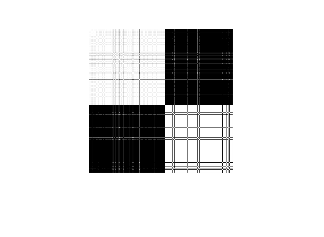

sums =          0  274.4621   57.6169         0         0         0         0         0         0         0


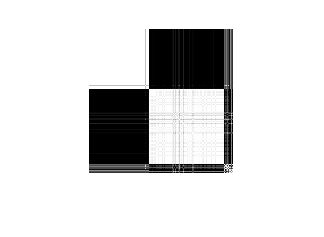

sums =          0  274.4621   57.6169   42.5598         0         0         0         0         0         0


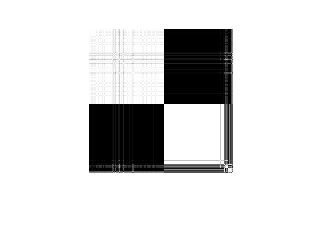

sums =          0  274.4621   57.6169   42.5598   43.3162         0         0         0         0         0


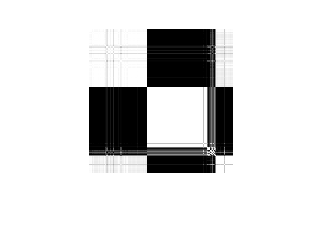

sums =          0  274.4621   57.6169   42.5598   43.3162   30.1039         0         0         0         0


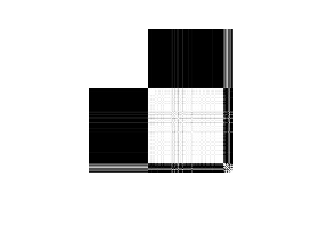

sums =          0  274.4621   57.6169   42.5598   43.3162   30.1039   18.3226         0         0         0


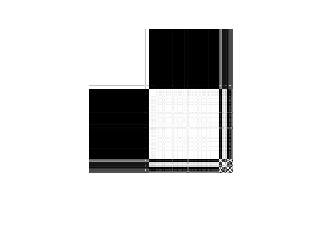

sums =          0  274.4621   57.6169   42.5598   43.3162   30.1039   18.3226   16.3139         0         0


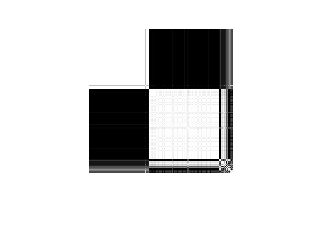

sums =          0  274.4621   57.6169   42.5598   43.3162   30.1039   18.3226   16.3139   18.7625         0


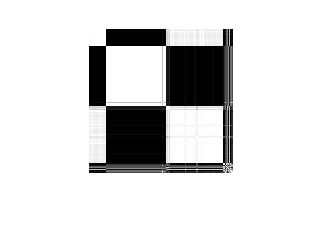

sums =          0  274.4621   57.6169   42.5598   43.3162   30.1039   18.3226   16.3139   18.7625    9.5802


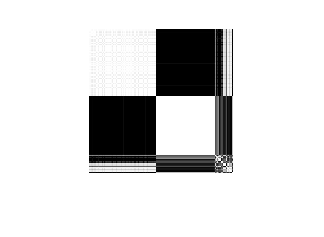

output = sol(:,sol(1,:).^2-4.*sol(2,:)<0);
[~,out_num] = size(output);
cor = zeros(out_num);
for i = 1 : out_num
    for j = 1 : out_num
        cor(i,j) = Distance(output(:,i),output(:,j));
    end
end
[u,s,v]=svd(cor);
Sam = cor*u(:,1:5);
sums = zeros(1,10);
C = {};
id = {};
for j = 2:10 % kmeans 的 k
[ind,M,sumd] = kmeans(Sam,j);
[~,I]=sort(ind);
newcor = cor(I,I);
img=mat2gray(newcor);%将数值矩阵X转换为灰度图像
C(j)={M};
id(j)={ind};
sums(j) = sum(sumd)
figure,imshow(img);
end

sums(1) = NaN; % 去掉 k = 1 无意义

sums =        NaN  274.4621   57.6169   42.5598   43.3162   30.1039   18.3226   16.3139   18.7625    9.5802


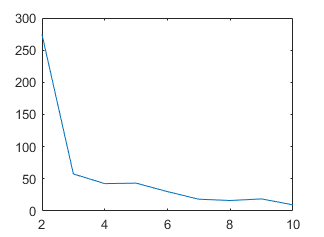

plot(sums) % 误差图 k = 3